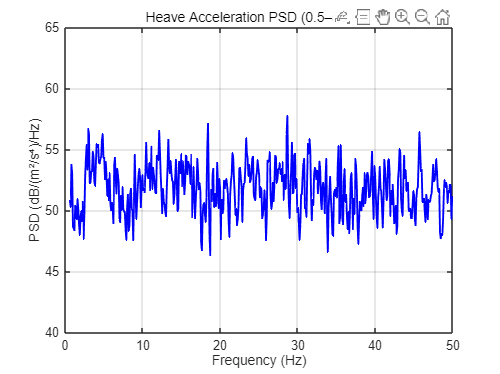

%% === Load Data ===
data = readtable('imu1.csv');       
t = data.Time_ms / 1000;            
Az_raw = data.AccelZ_g * 9.80665;   % Z-axis accel [m/s²]
dt = mean(diff(t));
fs = 1 / dt;                        

%% === High-pass Filter (Remove drift/gravity) ===
fc = 0.3;                           
[b, a] = butter(4, fc / (fs/2), 'high');
Az_filt = filtfilt(b, a, Az_raw);  

%% === PSD using Welch method ===
nfft = 1024;
window = hanning(nfft);
noverlap = nfft / 2;

[psd_vals, f] = pwelch(Az_filt, window, noverlap, nfft, fs);  

%% === Restrict Frequency Range to 0.5–50 Hz ===
idx = f >= 0.5 & f <= 50;
f_sel = f(idx);
psd_sel = psd_vals(idx);

%% === Plot PSD (0.5–50 Hz) ===
figure;
plot(f_sel, 10*log10(psd_sel), 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('PSD (dB/(m²/s⁴)/Hz)');
title('Heave Acceleration PSD (0.5–50 Hz)');
grid on;
ylim([40 65]);  % 🔧 Y축 범위 조절 (필요 시 수동 조정)


%% === Export Table (Optional) ===
T_psd = table(f_sel, psd_sel, ...
    'VariableNames', {'Frequency_Hz', 'PSD_m2s4_per_Hz'});
disp(T_psd);

    Frequency_Hz    PSD_m2s4_per_Hz
    ____________    _______________

      0.59096         1.2118e+05   
      0.68946         1.0783e+05   
      0.78795          2.395e+05   
      0.88644         2.0098e+05   
      0.98494              73934   
       1.0834              71912   
       1.1819              68906   
       1.2804         1.0982e+05   
       1.3789              86095   
       1.4774              85460   
       1.5759         1.2462e+05   
       1.6744         1.0293e+05   
       1.7729              76970   
       1.8714              63555   
       1.9699              90408   
       2.0684              99071   
       2.1669              81640   
       2.2654         1.1942e+05   
       2.3639              58474   
       2.4623              95609   
       2.5608         1.9073e+05   
       2.6593         2.6881e+05   
       2.7578          3.484e+05   
       2.8563         2.1738e+05   
       2.9548         4.6768e+05   
       3.0533         4.288


$$%% Parameter Values (Rendered as LaTeX in Live Script)

$$
K_{\mathrm{eff}} = 35~\mathrm{N/mm}, \quad
C_{\mathrm{COMP,front}} = 2.083~\mathrm{Ns/mm}, \quad
C_{\mathrm{REB,front}} = 1.727~\mathrm{Ns/mm}, \quad
C_{\mathrm{COMP,rear}} = 2.000~\mathrm{Ns/mm}, \quad
C_{\mathrm{REB,rear}} = 1.954~\mathrm{Ns/mm}
$$
$$
